# Loading Audio File and Image File

[y, Fs] = audioread("audio.wav");
player = audioplayer(y, Fs);
play(player);

stop(player);

lena = imread('lena_std.tif');
lena_gray = rgb2gray(lena)

lena_gray = 512×512 uint8 matrix
   162   162   162   161   162   157   163   161   165   161   162   160   155   163   160   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   165   161   162   160   155   163   160   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   165   161   162   160   155   163   160   155   157   156   161   161   154   156   154   157   155   157   155   152   156   154   154   156   154   158   155   160   158   167   160   166   166   165   166   172   171   175   173   170   172   172
   162   162   162   161   162   157   163   161   165   161   1

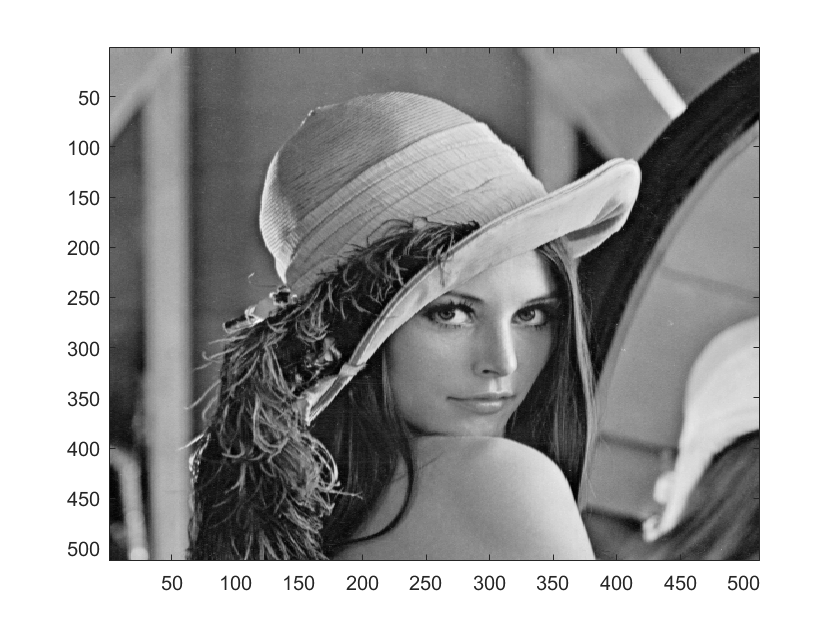

figure;
imagesc(lena_gray);
colormap('gray');

# Spread Spectrum Coding Method

% encryted the image by key
key = 3;
lena_gray_en = encryption2D(lena_gray, key);
% convert image from decimal to binary
lena_gray_ext = de2bi(lena_gray_en.');

img_size = 512;
crop_range = img_size*img_size*8*2+1;

% transform the audio from time domain to frequency domain
Y = fft(y(1:crop_range));
Y_phase = angle(Y);
Y_mag = abs(Y);

% scaling : turn float into integer to better convert to binary
scaled = 1000000;
Y_mag_scaled = floor(Y_mag*scaled);
Y_mag_ext = de2bi(Y_mag_scaled);

% embedding : put image's bits into LSB of audio signal
t = 1;
for i = 1:img_size*img_size
    for j = 1:8
        Y_mag_ext(t+1, 11) = lena_gray_ext(i, j);
        Y_mag_ext(crop_range-t+1, 11) = lena_gray_ext(i, j);
        t = t + 1;
    end
end

% check if the embedded audio signal changed or not
Y_mag_re = bi2de(Y_mag_ext)/scaled;
Y_re = Y_mag_re.*exp(1j*Y_phase);
y_re = ifft(Y_re);

% correction : turn complex signal into real signal (sound)
% y_re_c = zeros(crop_range, 1);
% for t = 1:length(y_re)
%     if (real(y_re(t)) >= 0)
%         y_re_c(t) = abs(y_re(t));
%     else
%         y_re_c(t) = -abs(y_re(t));
%     end
% end

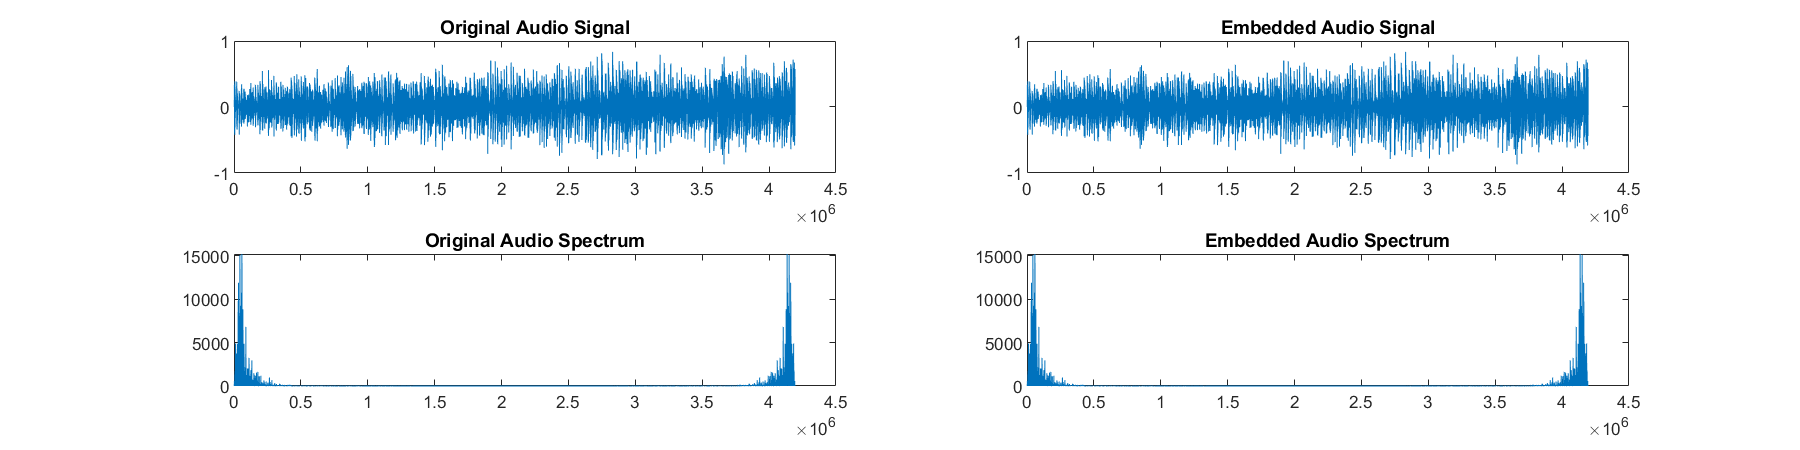

% plotting
figure;
set(gcf, 'Position',  [100, 100, 1200, 300]);
subplot(2,2,1);
plot(y(1:crop_range));
title('Original Audio Signal');
subplot(2,2,2);
plot(real(y_re));
title('Embedded Audio Signal');
subplot(2,2,3);
plot(Y_mag);
title('Original Audio Spectrum');
subplot(2,2,4);
plot(Y_mag_re);
title('Embedded Audio Spectrum');

% retrieve image from the embedded signal
Y_mag_t = abs(fft(real(y_re)));
scaled = 1000000;
Y_mag_scaled_t = floor(Y_mag_t*scaled);
Y_mag_ext_t = de2bi(Y_mag_scaled_t);

N = 512;
lena_img_bin = zeros(N*N, 8);
t = 2;
for i = 1:N*N
    for j = 1:8
        lena_img_bin(i, j) = Y_mag_ext_t(t, 11);
        t = t + 1;
    end
end
lena_img_re = bi2de(lena_img_bin);
lena_img_re = reshape(lena_img_re, N, N).';

% decrypted using key
key = 3;
lena_img_de = decryption2D(lena_img_re, key);

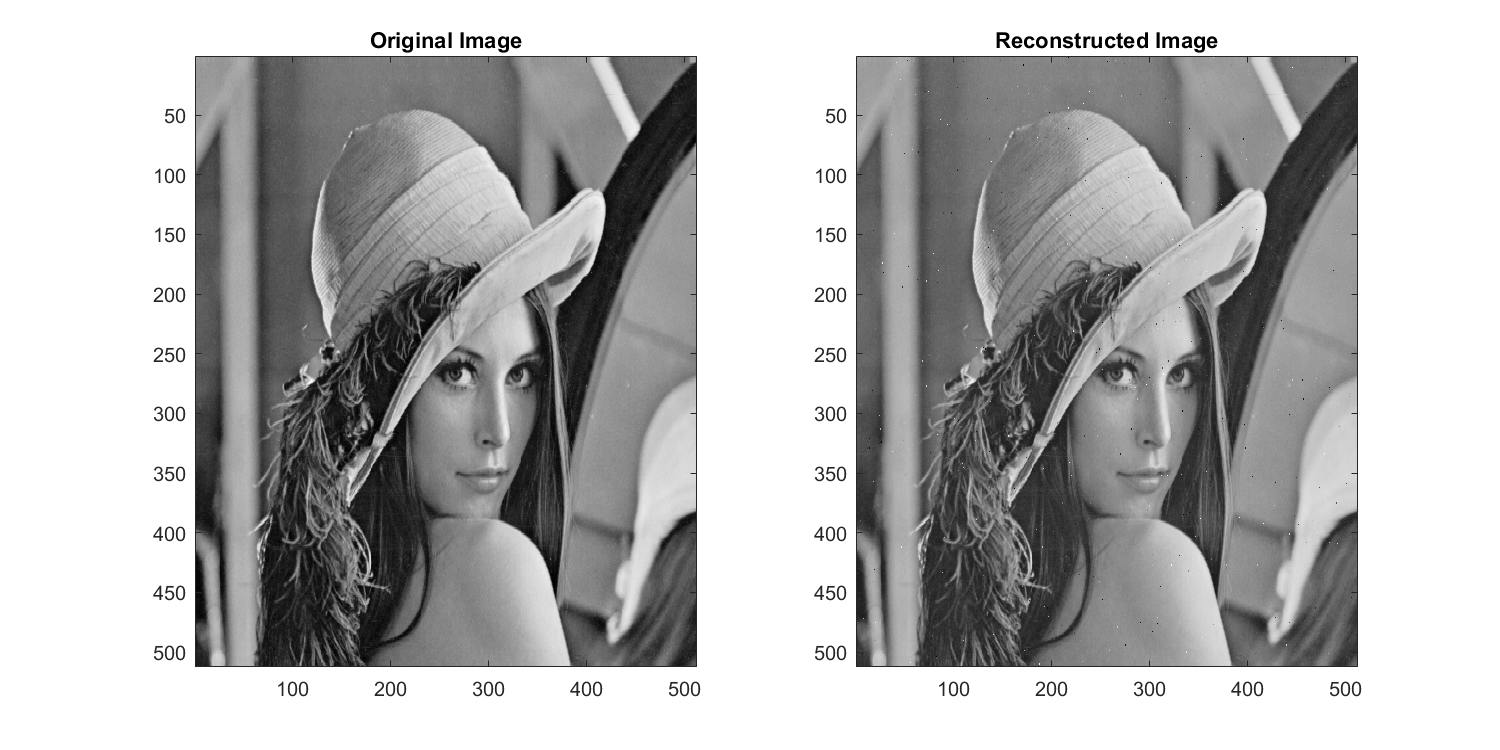

% plotting
figure;
colormap('gray');
set(gcf, 'Position',  [100, 100, 1000, 500]);
subplot(1,2,1);
imagesc(lena_gray);
title('Original Image');
subplot(1,2,2);
imagesc(lena_img_de);
title('Reconstructed Image');

## Audio Checking

playerObj = audioplayer(real(y_re),Fs);
play(playerObj);

stop(playerObj);

# Some qualitative results

Image

[peaksnr, snr] = psnr(lena_img_de/256, double(lena_gray)/256)

peaksnr = 37.7189

snr = 32.0281

mse = immse(lena_img_de/256, double(lena_gray)/256)

mse = 1.6909e-04

[ssimval, ssimmap] = ssim(lena_img_de/256, double(lena_gray)/256)

ssimval = 0.9739

ssimmap =     1.0000    1.0000    1.0000    0.9974    0.9824    0.9283    0.8288    0.7354    0.6979    0.7335    0.8306    0.9331    0.9848    0.9979    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9996    0.9982    0.9940    0.9875    0.9849    0.9889    0.9944    0.9980    0.9995    0.9999    0.9908    0.9375    0.7749
    1.0000    1.0000    1.0000    0.9985    0.9897    0.9560    0.8857    0.8077    0.7727    0.8061    0.8868    0.9590    0.9911    0.9988    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.9996    0.9974    0.9868    0.9573    0.9151    0.8987    0.9233    0.9598    0.9853    0.9966    0.9995    0.9727    0.832

Sound

[peaksnr, snr] = psnr(real(y_re), y(1:crop_range))

peaksnr = 129.0309

snr = 110.3919

mse = mean((real(y_re)-y(1:crop_range)).^2)

mse = 1.2500e-13

clear all;